clear
close all
load("Data\Regression\LandmarkPos.mat")

rt = RegressionTool;
for g = 1:3
    % select gender
    if g == 1
        Gender = 'm';
        k = 10;        
        MarkTable = MarkTableM; 
        step = size(MarkTable,1)/k;
    elseif g ==2 
        Gender = 'f';
        k = 9;        
        MarkTable = MarkTableF;
        step = size(MarkTable,1)/k;
    else
        Gender = 'all';
        k = 9
        step = 4;
        MarkTable = [MarkTableM;MarkTableF];
        index = randperm(38,38);
        MarkTable = MarkTable(index,:);
    end

    RegressEqu_Height = [];
    testError_Height = [];
    RegressEqu_Height_RowNames = [];
    testError_Height_ShankL = [];
    RegressEqu_Height_ShankL_RowNames = [];
    RegressEqu_Height_ShankM = [];
    testError_Height_ShankM = [];
    RegressEqu_Height_ShankM_RowNames = [];
    RegressEqu_KneeW = [];
    testError_KneeW = [];
    RegressEqu_KneeW_RowNames = [];
    RegressEqu_Height_AnkleW = [];
    testError_Height_AnkleW = [];
    RegressEqu_Height_AnkleW_RowNames = [];

    testErrorPer_Height = [];
    testErrorPer_Height_ShankL = [];
    testErrorPer_Height_ShankM = [];
    testErrorPer_KneeW = [];
    testErrorPer_Height_AnkleW = [];
    
    % k-fold cross validation
    for i = 1:k
        index = [step*i-1,step*(i)];
        if g == 3 
            index = [step*i-3,step*(i)-2,step*i-1,step*(i)];
        end
        % k-fold cross validation
        TrainTable = MarkTable;
        TrainTable(index,:) = [];
        TestTable = MarkTable(index,:);


    p = b_0+b_1*h

        k = 1;
        for j = 2:13            
            %(fold,test,pos)
            RegressEqu_Height(i,:,k) = rt.getRegressEqu(TrainTable.Height,TrainTable{:,j});
            testError_Height(i,:,k) = rt.getTestError_b0b1(TestTable.Height,TestTable{:,j},RegressEqu_Height(i,:,k));
            testErrorPer_Height(i,:,k) = rt.getTestErrorPer_b0b1(TestTable.Height,TestTable{:,j},RegressEqu_Height(i,:,k));
            RegressEqu_Height_RowNames{k} = MarkTable.Properties.VariableNames{j};     


            k = k+1;
        end


    p = b_0+b_1*h+b_2*s_L

        k = 1;
        for j = 9:3:12
            x1 = TrainTable.Height;
            x2 = TrainTable.RShankL;
            x = [x1,x2];
            RegressEqu_Height_ShankL(i,:,k) = rt.getRegressEqu(x,TrainTable{:,j});
            x1 = TestTable.Height;
            x2 = TestTable.RShankL;
            x = [x1,x2];
            testError_Height_ShankL(i,:,k) = rt.getTestError_b0b1b2(x,TestTable{:,j},RegressEqu_Height_ShankL(i,:,k));
            testErrorPer_Height_ShankL(i,:,k) = rt.getTestError_b0b1b2(x,TestTable{:,j},RegressEqu_Height_ShankL(i,:,k));
            RegressEqu_Height_ShankL_RowNames{k} = MarkTable.Properties.VariableNames{j};
            k = k+1;
        end

    p = b_0+b_1*h+b_2*s_M

        k = 1;
        for j = 9:3:12
            x1 = TrainTable.Height;
            x2 = TrainTable.RShankM;
            x = [x1,x2];
            RegressEqu_Height_ShankM(i,:,k) = rt.getRegressEqu(x,TrainTable{:,j});
            x1 = TestTable.Height;
            x2 = TestTable.RShankM;
            x = [x1,x2];
            testError_Height_ShankM(i,:,k) = rt.getTestError_b0b1b2(x,TestTable{:,j},RegressEqu_Height_ShankM(i,:,k));
            testErrorPer_Height_ShankM(i,:,k) = rt.getTestError_b0b1b2(x,TestTable{:,j},RegressEqu_Height_ShankM(i,:,k));
            RegressEqu_Height_ShankM_RowNames{k} = MarkTable.Properties.VariableNames{j};
            k = k+1;
        end


    p = b_0+b_1*k


        k = 1;
        for j = 4:3:7
            RegressEqu_KneeW(i,:,k) = rt.getRegressEqu(TrainTable.RKneeW,TrainTable{:,j});
            testError_KneeW(i,:,k) = rt.getTestError_b0b1(TestTable.RKneeW,TestTable{:,j},RegressEqu_KneeW(i,:,k));
            testErrorPer_KneeW(i,:,k) = rt.getTestError_b0b1(TestTable.RKneeW,TestTable{:,j},RegressEqu_KneeW(i,:,k));
            RegressEqu_KneeW_RowNames{k} = MarkTable.Properties.VariableNames{j};
            k = k+1;
        end

p = b_0+b_1*h+b_2*a

        k = 1;
        for j = 8:13
            if j == 9||j==12
                continue
            end
            x1 = TrainTable.Height;
            x2 = TrainTable.RAnkleW;
            x = [x1,x2];
            RegressEqu_Height_AnkleW(i,:,k) = rt.getRegressEqu(x,TrainTable{:,j});
            x1 = TestTable.Height;
            x2 = TestTable.RAnkleW;
            x = [x1,x2];
            testError_Height_AnkleW(i,:,k) = rt.getTestError_b0b1b2(x,TestTable{:,j},RegressEqu_Height_AnkleW(i,:,k));
            testErrorPer_Height_AnkleW(i,:,k) = rt.getTestError_b0b1b2(x,TestTable{:,j},RegressEqu_Height_AnkleW(i,:,k));
            RegressEqu_Height_AnkleW_RowNames{k} = MarkTable.Properties.VariableNames{j};
            k = k+1;
        end

    end
    if g == 1
        mRegressEqu_Height = RegressEqu_Height;
        mRegressEqu_Height_ShankL = RegressEqu_Height_ShankL;
        mRegressEqu_Height_ShankM = RegressEqu_Height_ShankM;
        mRegressEqu_KneeW = RegressEqu_KneeW;
        mRegressEqu_Height_AnkleW = RegressEqu_Height_AnkleW;

        
        mMeanRegressEqu_Height = reshape(mean(RegressEqu_Height),[6,12])';
        mRegressTable_Height = rt.getRegressTable(mMeanRegressEqu_Height,RegressEqu_Height_RowNames)        
        mMeanRegressEqu_Height_ShankL = reshape(mean(RegressEqu_Height_ShankL),[6,2])';
        mRegressTable_Height_ShankL = rt.getRegressTable(mMeanRegressEqu_Height_ShankL,RegressEqu_Height_ShankL_RowNames)        
        mMeanRegressEqu_Height_ShankM = reshape(mean(RegressEqu_Height_ShankM),[6,2])';
        mRegressTable_Height_ShankM = rt.getRegressTable(mMeanRegressEqu_Height_ShankM,RegressEqu_Height_ShankL_RowNames)        
        mMeanRegressEqu_KneeW = reshape(mean(RegressEqu_KneeW),[6,2])';
        mRegressTable_KneeW = rt.getRegressTable(mMeanRegressEqu_KneeW,RegressEqu_KneeW_RowNames)        
        mMeanRegressEqu_Height_AnkleW = reshape(mean(RegressEqu_Height_AnkleW),[6,4])';
        mRegressTable_Height_AnkleW = rt.getRegressTable(mMeanRegressEqu_Height_AnkleW,RegressEqu_Height_AnkleW_RowNames)

        [mMeanError_Height_Test,mSDError_Height_Test] = rt.getTestErrorMeanSD(testError_Height);
        [mMeanError_Height_ShankL_Test,mSDError_Height_ShankL_Test] = rt.getTestErrorMeanSD(testError_Height_ShankL);
        [mMeanError_Height_ShankM_Test,mSDError_Height_ShankM_Test] = rt.getTestErrorMeanSD(testError_Height_ShankM);
        [mMeanError_KneeW_Test,mSDError_KneeW_Test] = rt.getTestErrorMeanSD(testError_KneeW);
        [mMeanError_Height_AnkleW_Test,mSDError_Height_AnkleW_Test] = rt.getTestErrorMeanSD(testError_Height_AnkleW);

        [mMeanErrorPer_Height_Test,mSDErrorPer_Height_Test] = rt.getTestErrorMeanSD(testErrorPer_Height);
        [mMeanErrorPer_Height_ShankL_Test,mSDErrorPer_Height_ShankL_Test] = rt.getTestErrorMeanSD(testErrorPer_Height_ShankL);
        [mMeanErrorPer_Height_ShankM_Test,mSDErrorPer_Height_ShankM_Test] = rt.getTestErrorMeanSD(testErrorPer_Height_ShankM);
        [mMeanErrorPer_KneeW_Test,mSDErrorPer_KneeW_Test] = rt.getTestErrorMeanSD(testErrorPer_KneeW);
        [mMeanErrorPer_Height_AnkleW_Test,mSDErrorPer_Height_AnkleW_Test] = rt.getTestErrorMeanSD(testErrorPer_Height_AnkleW);

    elseif g==2
        fRegressEqu_Height = RegressEqu_Height;
        fRegressEqu_Height_ShankL = RegressEqu_Height_ShankL;
        fRegressEqu_Height_ShankM = RegressEqu_Height_ShankM;
        fRegressEqu_KneeW = RegressEqu_KneeW;
        fRegressEqu_Height_AnkleW = RegressEqu_Height_AnkleW;

        fMeanRegressEqu_Height = reshape(mean(RegressEqu_Height),[6,12])';
        fRegressTable_Height = rt.getRegressTable(fMeanRegressEqu_Height,RegressEqu_Height_RowNames)
        fMeanRegressEqu_Height_ShankL = reshape(mean(RegressEqu_Height_ShankL),[6,2])';
        fRegressTable_Height_ShankL = rt.getRegressTable(fMeanRegressEqu_Height_ShankL,RegressEqu_Height_ShankL_RowNames)
        fMeanRegressEqu_Height_ShankM = reshape(mean(RegressEqu_Height_ShankM),[6,2])';
        fRegressTable_Height_ShankM = rt.getRegressTable(fMeanRegressEqu_Height_ShankM,RegressEqu_Height_ShankL_RowNames)
        fMeanRegressEqu_KneeW = reshape(mean(RegressEqu_KneeW),[6,2])';
        fRegressTable_KneeW = rt.getRegressTable(fMeanRegressEqu_KneeW,RegressEqu_KneeW_RowNames)
        fMeanRegressEqu_Height_AnkleW = reshape(mean(RegressEqu_Height_AnkleW),[6,4])';
        fRegressTable_Height_AnkleW = rt.getRegressTable(fMeanRegressEqu_Height_AnkleW,RegressEqu_Height_AnkleW_RowNames)

        [fMeanError_Height_Test,fSDError_Height_Test] = rt.getTestErrorMeanSD(testError_Height);
        [fMeanError_Height_ShankL_Test,fSDError_Height_ShankL_Test] = rt.getTestErrorMeanSD(testError_Height_ShankL);
        [fMeanError_Height_ShankM_Test,fSDError_Height_ShankM_Test] = rt.getTestErrorMeanSD(testError_Height_ShankM);
        [fMeanError_KneeW_Test,fSDError_KneeW_Test] = rt.getTestErrorMeanSD(testError_KneeW);
        [fMeanError_Height_AnkleW_Test,fSDError_Height_AnkleW_Test] = rt.getTestErrorMeanSD(testError_Height_AnkleW);

        [fMeanErrorPer_Height_Test,fSDErrorPer_Height_Test] = rt.getTestErrorMeanSD(testErrorPer_Height);
        [fMeanErrorPer_Height_ShankL_Test,fSDErrorPer_Height_ShankL_Test] = rt.getTestErrorMeanSD(testErrorPer_Height_ShankL);
        [fMeanErrorPer_Height_ShankM_Test,fSDErrorPer_Height_ShankM_Test] = rt.getTestErrorMeanSD(testErrorPer_Height_ShankM);
        [fMeanErrorPer_KneeW_Test,fSDErrorPer_KneeW_Test] = rt.getTestErrorMeanSD(testErrorPer_KneeW);
        [fMeanErrorPer_Height_AnkleW_Test,fSDErrorPer_Height_AnkleW_Test] = rt.getTestErrorMeanSD(testErrorPer_Height_AnkleW);
    else
        aRegressEqu_Height = RegressEqu_Height;
        aRegressEqu_Height_ShankL = RegressEqu_Height_ShankL;
        aRegressEqu_Height_ShankM = RegressEqu_Height_ShankM;
        aRegressEqu_KneeW = RegressEqu_KneeW;
        aRegressEqu_Height_AnkleW = RegressEqu_Height_AnkleW;

        aMeanRegressEqu_Height = reshape(mean(RegressEqu_Height),[6,12])';
        aRegressTable_Height = rt.getRegressTable(aMeanRegressEqu_Height,RegressEqu_Height_RowNames)
        aMeanRegressEqu_Height_ShankL = reshape(mean(RegressEqu_Height_ShankL),[6,2])';
        aRegressTable_Height_ShankL = rt.getRegressTable(aMeanRegressEqu_Height_ShankL,RegressEqu_Height_ShankL_RowNames)
        aMeanRegressEqu_Height_ShankM = reshape(mean(RegressEqu_Height_ShankM),[6,2])';
        aRegressTable_Height_ShankM = rt.getRegressTable(aMeanRegressEqu_Height_ShankM,RegressEqu_Height_ShankL_RowNames)
        aMeanRegressEqu_KneeW = reshape(mean(RegressEqu_KneeW),[6,2])';
        aRegressTable_KneeW = rt.getRegressTable(aMeanRegressEqu_KneeW,RegressEqu_KneeW_RowNames)
        aMeanRegressEqu_Height_AnkleW = reshape(mean(RegressEqu_Height_AnkleW),[6,4])';
        aRegressTable_Height_AnkleW = rt.getRegressTable(aMeanRegressEqu_Height_AnkleW,RegressEqu_Height_AnkleW_RowNames)

        [aMeanError_Height_Test,aSDError_Height_Test] = rt.getTestErrorMeanSD(testError_Height);
        [aMeanError_Height_ShankL_Test,aSDError_Height_ShankL_Test] = rt.getTestErrorMeanSD(testError_Height_ShankL);
        [aMeanError_Height_ShankM_Test,aSDError_Height_ShankM_Test] = rt.getTestErrorMeanSD(testError_Height_ShankM);
        [aMeanError_KneeW_Test,aSDError_KneeW_Test] = rt.getTestErrorMeanSD(testError_KneeW);
        [aMeanError_Height_AnkleW_Test,aSDError_Height_AnkleW_Test] = rt.getTestErrorMeanSD(testError_Height_AnkleW);

        [aMeanErrorPer_Height_Test,aSDErrorPer_Height_Test] = rt.getTestErrorMeanSD(testErrorPer_Height);
        [aMeanErrorPer_Height_ShankL_Test,aSDErrorPer_Height_ShankL_Test] = rt.getTestErrorMeanSD(testErrorPer_Height_ShankL);
        [aMeanErrorPer_Height_ShankM_Test,aSDErrorPer_Height_ShankM_Test] = rt.getTestErrorMeanSD(testErrorPer_Height_ShankM);
        [aMeanErrorPer_KneeW_Test,aSDErrorPer_KneeW_Test] = rt.getTestErrorMeanSD(testErrorPer_KneeW);
        [aMeanErrorPer_Height_AnkleW_Test,aSDErrorPer_Height_AnkleW_Test] = rt.getTestErrorMeanSD(testErrorPer_Height_AnkleW);


    end



end

mRegressTable_Height = 12×6 table
               b0           b1         b2     RSqure       p-Value        SD  
             _______    ___________    __    _________    __________    ______

    REFMX          0              0    0           NaN           NaN         0
    REFMY    -11.949       -0.23211    0       0.24029      0.042426    21.465
    REFMZ    -51.859     0.00096682    0     0.0067331       0.81123    4.1089
    REFLX          0              0    0           NaN           NaN         0
    REFLY    -3.1015       -0.23789    0       0.23825      0.042834    22.088
    REFLZ     51.859    -0.00096682    0     0.0067331       0.81123    4.1089
    RMMX     -65.268       0.045241    0        0.1356       0.17903    6.1697
    RMMY      156.41       -0.31194    0       0.60325    0.00020311    13.099
    RMMZ     -37.062      0.0037473    0      0.017739       0.68626    3.6403
    RLMX      65.268      -0.045241    0        0.1356       0.17903    6.1697
    RLMY      125

mRegressTable_Height_ShankL = 2×6 table
              b0          b1           b2       RSqure      p-Value        SD  
            ______    __________    ________    _______    __________    ______

    RMMY    62.698      -0.08354    -0.76622    0.90017    5.3608e-08    6.5513
    RLMY    2.8297    -0.0017176    -0.99914    0.99406    3.3332e-17     1.648


mRegressTable_Height_ShankM = 2×6 table
              b0           b1            b2       RSqure      p-Value        SD  
            _______    ___________    ________    _______    __________    ______

    RMMY    -3.6414    -0.00095696    -0.98267    0.99417    2.4986e-17    1.5869
    RLMY    -31.098      0.0046158    -0.96214    0.87185    3.1301e-07    7.6771


mRegressTable_KneeW = 2×6 table
                b0           b1       b2    RSqure      p-Value         SD   
             _________    ________    __    _______    __________    ________

    REFMZ    -0.051663    -0.49921    0     0.99992    7.5556e-34    0.037459
    REFLZ     0.051663     0.49921    0     0.99992    7.5556e-34    0.037459


mRegressTable_Height_AnkleW = 4×6 table
              b0          b1           b2       RSqure     p-Value       SD  
            _______    _________    ________    _______    ________    ______

    RMMX    -67.707     0.053466    -0.17226    0.14356     0.34757    6.1411
    RMMZ    -44.878     0.031291    -0.58179     0.2791    0.091873    3.1173
    RLMX     67.707    -0.053466     0.17226    0.14356     0.34757    6.1411
    RLMZ     44.878    -0.031291     0.58179     0.2791    0.091873    3.1173


fRegressTable_Height = 12×6 table
               b0          b1        b2     RSqure      p-Value        SD  
             _______    _________    __    ________    __________    ______

    REFMX          0            0    0          NaN           NaN         0
    REFMY     568.01     -0.58419    0      0.82131    3.7705e-06    13.329
    REFMZ     49.089    -0.059936    0       0.3945      0.012324    3.6813
    REFLX          0            0    0          NaN           NaN         0
    REFLY     494.03     -0.53872    0      0.82548    3.9435e-06    12.105
    REFLZ    -49.089     0.059936    0       0.3945      0.012324    3.6813
    RMMX      27.017    -0.010697    0     0.026902       0.58362    3.9307
    RMMY      28.396     -0.23814    0      0.28816      0.041283    18.052
    RMMZ      13.842    -0.025786    0       0.2369      0.062481     2.287
    RLMX     -27.017     0.010697    0     0.026902       0.58362    3.9307
    RLMY      87.397     -0.28059    0       0.3373  

fRegressTable_Height_ShankL = 2×6 table
              b0          b1          b2       RSqure      p-Value        SD  
            _______    ________    ________    _______    __________    ______

    RMMY    -66.412    0.018946    -0.87419    0.88684    9.8926e-07    7.1789
    RLMY    -35.334    0.023792     -1.0074    0.99514    1.2042e-15    1.6011


fRegressTable_Height_ShankM = 2×6 table
              b0         b1           b2       RSqure      p-Value        SD  
            ______    _________    ________    _______    __________    ______

    RMMY    35.417     -0.02569    -0.98018    0.99496    1.7419e-15    1.5153
    RLMY    94.747    -0.073926     -0.9549    0.89607     4.721e-07    7.5697


fRegressTable_KneeW = 2×6 table
                b0          b1       b2    RSqure      p-Value         SD   
             ________    ________    __    _______    __________    ________

    REFMZ    -0.15172    -0.49806    0     0.99984    1.2307e-27    0.058491
    REFLZ     0.15172     0.49806    0     0.99984    1.2307e-27    0.058491


fRegressTable_Height_AnkleW = 4×6 table
              b0          b1          b2       RSqure      p-Value       SD  
            _______    _________    _______    _______    _________    ______

    RMMX     32.367    -0.029388     0.4091    0.32445      0.10836    3.2571
    RMMZ     9.6133    -0.011409     -0.313    0.63152    0.0023784    1.5767
    RLMX    -32.367     0.029388    -0.4091    0.32445      0.10836    3.2571
    RLMZ    -9.6133     0.011409      0.313    0.63152    0.0023784    1.5767


k = 9

aRegressTable_Height = 12×6 table
               b0          b1        b2    RSqure      p-Value        SD  
             _______    _________    __    _______    __________    ______

    REFMX          0            0    0         NaN           NaN         0
    REFMY     154.07     -0.32781    0     0.65387    9.1045e-09    20.237
    REFMZ    -17.968    -0.018451    0     0.12391      0.045879    4.1822
    REFLX          0            0    0         NaN           NaN         0
    REFLY     152.75     -0.32749    0     0.66928    4.4317e-09    19.532
    REFLZ     17.968     0.018451    0     0.12391      0.045879    4.1822
    RMMX     -38.298     0.029748    0     0.18199      0.018037    5.3952
    RMMY      64.728     -0.26013    0     0.66424    7.6712e-09    15.691
    RMMZ     -3.8934    -0.015001    0     0.14443       0.04083    3.1489
    RLMX      38.298    -0.029748    0     0.18199      0.018037    5.3952
    RLMY      58.733     -0.26234    0      0.6339    4.0372e-08 

aRegressTable_Height_ShankL = 2×6 table
              b0          b1           b2       RSqure      p-Value        SD  
            _______    _________    ________    _______    __________    ______

    RMMY     17.977    -0.042616    -0.83299    0.92808    1.0555e-10    7.0954
    RLMY    -1.6365    0.0014732     -1.0013    0.99559      1.69e-18     1.792


aRegressTable_Height_ShankM = 2×6 table
              b0           b1           b2       RSqure      p-Value        SD  
            _______    __________    ________    _______    __________    ______

    RMMY     1.2394    -0.0052348    -0.97663    0.99596    2.5372e-37    1.7176
    RLMY    -2.2439     -0.017827    -0.93665    0.92088    1.5882e-17    7.8588


aRegressTable_KneeW = 2×6 table
                b0           b1       b2    RSqure      p-Value         SD   
             _________    ________    __    _______    __________    ________

    REFMZ    -0.090967    -0.49876    0     0.99988    2.5276e-63    0.048729
    REFLZ     0.090967     0.49876    0     0.99988    2.5276e-63    0.048729


aRegressTable_Height_AnkleW = 4×6 table
              b0           b1           b2       RSqure      p-Value        SD  
            _______    __________    ________    _______    __________    ______

    RMMX     -29.46      0.014384     0.26186    0.22121      0.026033     5.265
    RMMZ    -16.977     0.0079395    -0.39252    0.39475    0.00086956    2.6463
    RLMX      29.46     -0.014384    -0.26186    0.22121      0.026033     5.265
    RLMZ     16.977    -0.0079395     0.39252    0.39475    0.00086956    2.6463


load('Data\Regression\MarkTableXsens.mat')

h = 1500:200:1900;
figure %p = b_0+b_1h
set(gca,'FontName','Times New Roman','FontSize',8,'LineWidth',0.5);
set(gcf,'unit','centimeters','position',[1,1,16,20]);
lineWidth = 0.05;
%X
my = mRegressEqu_Height(:,1,7)+mRegressEqu_Height(:,2,7)*h

my =     1.4160   11.0820   20.7479
   -0.2242   11.3039   22.8321
    2.9673   11.5852   20.2031
    3.0997   12.2031   21.3064
    1.5386   11.3415   21.1445
   10.3824   13.0009   15.6194
    1.7764   10.9514   20.1263
    0.2945   11.8806   23.4667
    0.8521   10.8163   20.7804
    3.8297   12.2488   20.6678


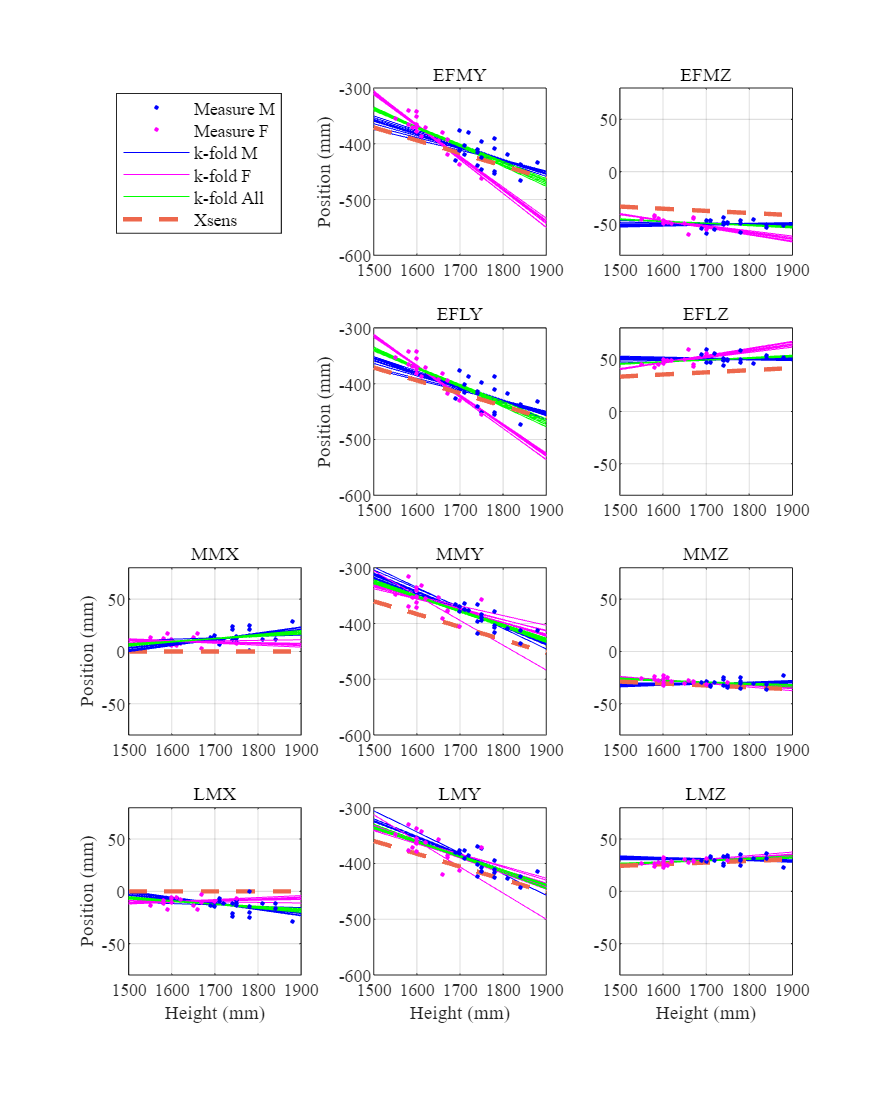

fy = fRegressEqu_Height(:,1,7)+fRegressEqu_Height(:,2,7)*h;
ay = aRegressEqu_Height(:,1,7)+aRegressEqu_Height(:,2,7)*h;

subplot(4,3,7);hold on;title('MMX');xlim([1500,1900]);ylim([-80,80]);box on;grid on;
set(gca,'FontName','Times New Roman','FontSize',8,'LineWidth',0.5);
plot(MarkTableM.Height,MarkTableM{:,8},'b.')
plot(MarkTableF.Height,MarkTableF{:,8},'m.')
plot(h,my(1,:),'b',LineWidth = lineWidth);
plot(h,fy(1,:),'m',LineWidth = lineWidth);
plot(h,ay(1,:),'g',LineWidth = lineWidth);
plot(MarkTableXsens.("Height(cm)"),MarkTableXsens.RMMX,	'--', Color = [237,103,76]./255,LineWidth=2)
plot(h,my,'b',LineWidth = lineWidth);
plot(h,fy,'m',LineWidth = lineWidth);
plot(h,ay,'g',LineWidth = lineWidth);
ylabel('Position (mm)')
ylabel('Position (mm)')

legend({'Measure M','Measure F','k-fold M','k-fold F','k-fold All','Xsens'})
legend("Position", [0.16476,0.80488,0.12556,0.091518])
legend('FontSize',8)

my = mRegressEqu_Height(:,1,10)+mRegressEqu_Height(:,2,10)*h;
fy = fRegressEqu_Height(:,1,10)+fRegressEqu_Height(:,2,10)*h;
ay = aRegressEqu_Height(:,1,10)+aRegressEqu_Height(:,2,10)*h;

subplot(4,3,10);hold on;title('LMX');xlim([1500,1900]);ylim([-80,80]);box on;grid on;
set(gca,'FontName','Times New Roman','FontSize',8,'LineWidth',0.5);
plot(h,my,'b',LineWidth = lineWidth);
plot(h,fy,'m',LineWidth = lineWidth);
plot(h,ay,'g',LineWidth = lineWidth);
plot(MarkTableXsens.("Height(cm)"),MarkTableXsens.RLMX,	'--', Color = [237,103,76]./255,LineWidth=2)
plot(MarkTableM.Height,MarkTableM{:,11},'b.')
plot(MarkTableF.Height,MarkTableF{:,11},'m.')
xlabel('Height (mm)')
ylabel('Position (mm)')

%Y
my = mRegressEqu_Height(:,1,2)+mRegressEqu_Height(:,2,2)*h;
fy = fRegressEqu_Height(:,1,2)+fRegressEqu_Height(:,2,2)*h;
ay = aRegressEqu_Height(:,1,2)+aRegressEqu_Height(:,2,2)*h;

subplot(4,3,2);hold on;title('EFMY');xlim([1500,1900]);ylim([-600,-300]);box on;grid on;
set(gca,'FontName','Times New Roman','FontSize',8,'LineWidth',0.5);
plot(h,my,'b',LineWidth = lineWidth);
plot(h,fy,'m',LineWidth = lineWidth);
plot(h,ay,'g',LineWidth = lineWidth);
plot(MarkTableXsens.("Height(cm)"),MarkTableXsens.REFMY,	'--', Color = [237,103,76]./255,LineWidth=2)
plot(MarkTableM.Height,MarkTableM{:,3},'b.')
plot(MarkTableF.Height,MarkTableF{:,3},'m.')
ylabel('Position (mm)')

my = mRegressEqu_Height(:,1,5)+mRegressEqu_Height(:,2,5)*h;
fy = fRegressEqu_Height(:,1,5)+fRegressEqu_Height(:,2,5)*h;
ay = aRegressEqu_Height(:,1,5)+aRegressEqu_Height(:,2,5)*h;
subplot(4,3,5);hold on;title('EFLY');xlim([1500,1900]);ylim([-600,-300]);box on;grid on;
set(gca,'FontName','Times New Roman','FontSize',8,'LineWidth',0.5);
plot(h,my,'b',LineWidth = lineWidth);
plot(h,fy,'m',LineWidth = lineWidth);
plot(h,ay,'g',LineWidth = lineWidth);
plot(MarkTableM.Height,MarkTableM{:,6},'b.')
plot(MarkTableF.Height,MarkTableF{:,6},'m.')
plot(MarkTableXsens.("Height(cm)"),MarkTableXsens.REFLY,	'--', Color = [237,103,76]./255,LineWidth=2)
ylabel('Position (mm)')

my = mRegressEqu_Height(:,1,8)+mRegressEqu_Height(:,2,8)*h;
fy = fRegressEqu_Height(:,1,8)+fRegressEqu_Height(:,2,8)*h;
ay = aRegressEqu_Height(:,1,8)+aRegressEqu_Height(:,2,8)*h;
subplot(4,3,8);hold on;title('MMY');xlim([1500,1900]);ylim([-600,-300]);box on;grid on;
set(gca,'FontName','Times New Roman','FontSize',8,'LineWidth',0.5);
plot(h,my,'b',LineWidth = lineWidth);
plot(h,fy,'m',LineWidth = lineWidth);
plot(h,ay,'g',LineWidth = lineWidth);
plot(MarkTableXsens.("Height(cm)"),MarkTableXsens.RMMY,	'--', Color = [237,103,76]./255,LineWidth=2)
plot(MarkTableM.Height,MarkTableM{:,9},'b.')
plot(MarkTableF.Height,MarkTableF{:,9},'m.')

my = mRegressEqu_Height(:,1,11)+mRegressEqu_Height(:,2,11)*h;
fy = fRegressEqu_Height(:,1,11)+fRegressEqu_Height(:,2,11)*h;
ay = aRegressEqu_Height(:,1,11)+aRegressEqu_Height(:,2,11)*h;
subplot(4,3,11);hold on;title('LMY');xlim([1500,1900]);ylim([-600,-300]);box on;grid on;
set(gca,'FontName','Times New Roman','FontSize',8,'LineWidth',0.5);
plot(h,my,'b',LineWidth = lineWidth);
plot(h,fy,'m',LineWidth = lineWidth);
plot(h,ay,'g',LineWidth = lineWidth);
plot(MarkTableXsens.("Height(cm)"),MarkTableXsens.RLMY,	'--', Color = [237,103,76]./255,LineWidth=2)
plot(MarkTableM.Height,MarkTableM{:,12},'b.')
plot(MarkTableF.Height,MarkTableF{:,12},'m.')
xlabel('Height (mm)')

%Z
my = mRegressEqu_Height(:,1,3)+mRegressEqu_Height(:,2,3)*h;
fy = fRegressEqu_Height(:,1,3)+fRegressEqu_Height(:,2,3)*h;
ay = aRegressEqu_Height(:,1,3)+aRegressEqu_Height(:,2,3)*h;
subplot(4,3,3);hold on;title('EFMZ');xlim([1500,1900]);ylim([-80,80]);box on;grid on;
set(gca,'FontName','Times New Roman','FontSize',8,'LineWidth',0.5);
plot(h,my,'b',LineWidth = lineWidth);
plot(h,fy,'m',LineWidth = lineWidth);
plot(h,ay,'g',LineWidth = lineWidth);
plot(MarkTableXsens.("Height(cm)"),MarkTableXsens.REFMZ,	'--', Color = [237,103,76]./255,LineWidth=2)
plot(MarkTableM.Height,MarkTableM{:,4},'b.')
plot(MarkTableF.Height,MarkTableF{:,4},'m.')

my = mRegressEqu_Height(:,1,6)+mRegressEqu_Height(:,2,6)*h;
fy = fRegressEqu_Height(:,1,6)+fRegressEqu_Height(:,2,6)*h;
ay = aRegressEqu_Height(:,1,6)+aRegressEqu_Height(:,2,6)*h;
subplot(4,3,6);hold on;title('EFLZ');xlim([1500,1900]);ylim([-80,80]);box on;grid on;
set(gca,'FontName','Times New Roman','FontSize',8,'LineWidth',0.5);
plot(h,my,'b',LineWidth = lineWidth);
plot(h,fy,'m',LineWidth = lineWidth);
plot(h,ay,'g',LineWidth = lineWidth);
plot(MarkTableXsens.("Height(cm)"),MarkTableXsens.REFLZ,	'--', Color = [237,103,76]./255,LineWidth=2)
plot(MarkTableM.Height,MarkTableM{:,7},'b.')
plot(MarkTableF.Height,MarkTableF{:,7},'m.')

my = mRegressEqu_Height(:,1,9)+mRegressEqu_Height(:,2,9)*h;
fy = fRegressEqu_Height(:,1,9)+fRegressEqu_Height(:,2,9)*h;
ay = aRegressEqu_Height(:,1,9)+aRegressEqu_Height(:,2,9)*h;
subplot(4,3,9);hold on;title('MMZ');xlim([1500,1900]);ylim([-80,80]);box on;grid on;
set(gca,'FontName','Times New Roman','FontSize',8,'LineWidth',0.5);
plot(h,my,'b',LineWidth = lineWidth);
plot(h,fy,'m',LineWidth = lineWidth);
plot(h,ay,'g',LineWidth = lineWidth);
plot(MarkTableXsens.("Height(cm)"),MarkTableXsens.RMMZ,	'--', Color = [237,103,76]./255,LineWidth=2)
plot(MarkTableM.Height,MarkTableM{:,10},'b.')
plot(MarkTableF.Height,MarkTableF{:,10},'m.')

my = mRegressEqu_Height(:,1,12)+mRegressEqu_Height(:,2,12)*h;
fy = fRegressEqu_Height(:,1,12)+fRegressEqu_Height(:,2,12)*h;
ay = aRegressEqu_Height(:,1,12)+aRegressEqu_Height(:,2,12)*h;
subplot(4,3,12);hold on;title('LMZ');xlim([1500,1900]);ylim([-80,80]);box on;grid on;
set(gca,'FontName','Times New Roman','FontSize',8,'LineWidth',0.5);
plot(h,my,'b',LineWidth = lineWidth);
plot(h,fy,'m',LineWidth = lineWidth);
plot(h,ay,'g',LineWidth = lineWidth);
plot(MarkTableXsens.("Height(cm)"),MarkTableXsens.RLMZ,	'--', Color = [237,103,76]./255,LineWidth=2)
plot(MarkTableM.Height,MarkTableM{:,13},'b.')
plot(MarkTableF.Height,MarkTableF{:,13},'m.')
xlabel('Height (mm)')

meanError = [];
stdError = [];
for i = 2:13
    x = MarkTableXsens.("Height(cm)");
    y = MarkTableXsens{:,i};
    mdl = fitlm(x,y);
    b0 = mdl.Coefficients.Estimate(1);
    b1 = mdl.Coefficients.Estimate(2);
    mError = b0+b1.*MarkTableM.Height-MarkTableM{:,i};
    fError = b0+b1.*MarkTableF.Height-MarkTableF{:,i};
    aError = b0+b1.*MarkTable.Height-MarkTable{:,i};

    mMeanError(i-1) = mean(mError);
    mSDError(i-1) = std(mError);

    fMeanError(i-1) = mean(fError);
    fSDError(i-1) = std(fError);

    aMeanError(i-1) = mean(aError);
    aSDError(i-1) = std(aError);

end

for i = 1:12
    mErrorXsens{i} = [num2str(mMeanError(i),'%.1f'),'±',num2str(mSDError(i),'%.1f')];
    fErrorXsens{i} = [num2str(fMeanError(i),'%.1f'),'±',num2str(fSDError(i),'%.1f')];
    aErrorXsens{i} = [num2str(aMeanError(i),'%.1f'),'±',num2str(aSDError(i),'%.1f')];
end

mTemp = reshape(mErrorXsens,3,4)';
fTemp = reshape(fErrorXsens,3,4)';
aTemp = reshape(aErrorXsens,3,4)';

mErrorTable = cell2table(mTemp);
mErrorTable.Properties.VariableNames = {'X','Y','Z'};
mErrorTable.Properties.RowNames = {'REFM','REFL','RMM','RLM'}

mErrorTable = 4×3 table
                  X                Y                 Z      
            _____________    ______________    _____________

    REFM    {'0.0±0.0'  }    {'-9.9±21.5' }    {'11.4±4.3' }
    REFL    {'0.0±0.0'  }    {'-9.0±22.1' }    {'-11.4±4.3'}
    RMM     {'-14.3±6.6'}    {'-27.2±13.8'}    {'-3.1±3.9' }
    RLM     {'14.3±6.6' }    {'-17.3±15.4'}    {'-2.0±3.8' }



fErrorTable = cell2table(fTemp);
fErrorTable.Properties.VariableNames = {'X','Y','Z'};
fErrorTable.Properties.RowNames = {'REFM','REFL','RMM','RLM'}

fErrorTable = 4×3 table
                 X                Y                 Z      
            ____________    ______________    _____________

    REFM    {'0.0±0.0' }    {'-18.6±22.2'}    {'12.3±4.2' }
    REFL    {'0.0±0.0' }    {'-18.8±19.6'}    {'-12.3±4.2'}
    RMM     {'-9.6±4.0'}    {'-30.2±18.4'}    {'-3.1±2.3' }
    RLM     {'9.6±4.0' }    {'-19.9±19.4'}    {'-1.7±2.3' }



aErrorTable = cell2table(aTemp);
aErrorTable.Properties.VariableNames = {'X','Y','Z'};
aErrorTable.Properties.RowNames = {'REFM','REFL','RMM','RLM'}

aErrorTable = 4×3 table
                  X                Y                 Z      
            _____________    ______________    _____________

    REFM    {'0.0±0.0'  }    {'-14.0±22.0'}    {'11.9±4.2' }
    REFL    {'0.0±0.0'  }    {'-13.7±21.3'}    {'-11.9±4.2'}
    RMM     {'-12.1±6.0'}    {'-28.6±16.0'}    {'-3.1±3.2' }
    RLM     {'12.1±6.0' }    {'-18.5±17.2'}    {'-1.9±3.2' }



% For Word
mRegress = [mMeanRegressEqu_Height;...
    mMeanRegressEqu_Height_ShankL;...
    mMeanRegressEqu_Height_ShankM;...
    mMeanRegressEqu_KneeW;...
    mMeanRegressEqu_Height_AnkleW];

fRegress = [fMeanRegressEqu_Height;...
    fMeanRegressEqu_Height_ShankL;...
    fMeanRegressEqu_Height_ShankM;...
    fMeanRegressEqu_KneeW;...
    fMeanRegressEqu_Height_AnkleW];

aRegress = [aMeanRegressEqu_Height;...
    aMeanRegressEqu_Height_ShankL;...
    aMeanRegressEqu_Height_ShankM;...
    aMeanRegressEqu_KneeW;...
    aMeanRegressEqu_Height_AnkleW];

mRegress([1,4],:) = [];
fRegress([1,4],:) = [];
aRegress([1,4],:) = [];


mTestMeanError = [mMeanError_Height_Test';...
    mMeanError_Height_ShankL_Test';...
    mMeanError_Height_ShankM_Test';...
    mMeanError_KneeW_Test';...
    mMeanError_Height_AnkleW_Test'];
mTestSDError = [mSDError_Height_Test';...
    mSDError_Height_ShankL_Test';...
    mSDError_Height_ShankM_Test';...
    mSDError_KneeW_Test';...
    mSDError_Height_AnkleW_Test'];

fTestMeanError = [fMeanError_Height_Test';...
    fMeanError_Height_ShankL_Test';...
    fMeanError_Height_ShankM_Test';...
    fMeanError_KneeW_Test';...
    fMeanError_Height_AnkleW_Test'];

fTestSDError = [fSDError_Height_Test';...
    fSDError_Height_ShankL_Test';...
    fSDError_Height_ShankM_Test';...
    fSDError_KneeW_Test';...
    fSDError_Height_AnkleW_Test'];

aTestMeanError = [aMeanError_Height_Test';...
    aMeanError_Height_ShankL_Test';...
    aMeanError_Height_ShankM_Test';...
    aMeanError_KneeW_Test';...
    aMeanError_Height_AnkleW_Test'];
aTestSDError = [aSDError_Height_Test';...
    aSDError_Height_ShankL_Test';...
    aSDError_Height_ShankM_Test';...
    aSDError_KneeW_Test';...
    aSDError_Height_AnkleW_Test'];

mTestMeanError([1,4],:) = [];
mTestSDError([1,4],:) = [];
fTestMeanError([1,4],:) = [];
fTestSDError([1,4],:) = [];
aTestMeanError([1,4],:) = [];
aTestSDError([1,4],:) = [];



for i = 1:20
    mTestErrorStr{i,1} = [num2str(mTestMeanError(i),'%.1f'),'±',num2str(mTestSDError(i),'%.1f')];
    fTestErrorStr{i,1} = [num2str(fTestMeanError(i),'%.1f'),'±',num2str(fTestSDError(i),'%.1f')];
    aTestErrorStr{i,1} = [num2str(aTestMeanError(i),'%.1f'),'±',num2str(aTestSDError(i),'%.1f')];
    for j = 1:5
        mRegressStr{i,j} = num2str(mRegress(i,j),'%.3f');
        fRegressStr{i,j} = num2str(fRegress(i,j),'%.3f');
        aRegressStr{i,j} = num2str(aRegress(i,j),'%.3f');
    end
    mRegressStr{i,6} = mTestErrorStr{i,1};
    fRegressStr{i,6} = fTestErrorStr{i,1};
    aRegressStr{i,6} = aTestErrorStr{i,1};

end

CopyToWord = [mRegressStr;fRegressStr;aRegressStr]

CopyToWord = 60×6 cell 数组
    {'-11.949'}    {'-0.232'}    {'0.000' }    {'0.240'}    {'0.042'}    {'-0.0±23.3'}
    {'-51.859'}    {'0.001' }    {'0.000' }    {'0.007'}    {'0.811'}    {'-0.1±4.6' }
    {'-3.102' }    {'-0.238'}    {'0.000' }    {'0.238'}    {'0.043'}    {'0.1±24.0' }
    {'51.859' }    {'-0.001'}    {'0.000' }    {'0.007'}    {'0.811'}    {'0.1±4.6'  }
    {'-65.268'}    {'0.045' }    {'0.000' }    {'0.136'}    {'0.179'}    {'0.0±7.1'  }
    {'156.409'}    {'-0.312'}    {'0.000' }    {'0.603'}    {'0.000'}    {'0.2±15.0' }
    {'-37.062'}    {'0.004' }    {'0.000' }    {'0.018'}    {'0.686'}    {'0.0±4.4'  }
    {'65.268' }    {'-0.045'}    {'0.000' }    {'0.136'}    {'0.179'}    {'-0.0±7.1' }
    {'125.652'}    {'-0.300'}    {'0.000' }    {'0.521'}    {'0.001'}    {'0.3±17.3' }
    {'37.062' }    {'-0.004'}    {'0.000' }    {'0.018'}    {'0.686'}    {'-0.0±4.4' }
    {'62.698' }    {'-0.084'}    {'-0.766'}    {'0.900'}    {'0.000'}    {'-0.4±7.9' }
    {'2.830'  }  

CopyToWordXsens = [table2array(mErrorTable);table2array(fErrorTable);table2array(aErrorTable)]

CopyToWordXsens = 12×3 cell 数组
    {'0.0±0.0'  }    {'-9.9±21.5' }    {'11.4±4.3' }
    {'0.0±0.0'  }    {'-9.0±22.1' }    {'-11.4±4.3'}
    {'-14.3±6.6'}    {'-27.2±13.8'}    {'-3.1±3.9' }
    {'14.3±6.6' }    {'-17.3±15.4'}    {'-2.0±3.8' }
    {'0.0±0.0'  }    {'-18.6±22.2'}    {'12.3±4.2' }
    {'0.0±0.0'  }    {'-18.8±19.6'}    {'-12.3±4.2'}
    {'-9.6±4.0' }    {'-30.2±18.4'}    {'-3.1±2.3' }
    {'9.6±4.0'  }    {'-19.9±19.4'}    {'-1.7±2.3' }
    {'0.0±0.0'  }    {'-14.0±22.0'}    {'11.9±4.2' }
    {'0.0±0.0'  }    {'-13.7±21.3'}    {'-11.9±4.2'}
    {'-12.1±6.0'}    {'-28.6±16.0'}    {'-3.1±3.2' }
    {'12.1±6.0' }    {'-18.5±17.2'}    {'-1.9±3.2' }


for g = 1:2
    if g ==1
        markTable = MarkTableM;
        RegressTable_Height = mRegressTable_Height;
        RegressTable_KneeW = mRegressTable_KneeW;
        RegressTable_Height_ShankM = mRegressTable_Height_ShankM;
        RegressTable_Height_ShankL = mRegressTable_Height_ShankL;
        RegressTable_Height_AnkleW = mRegressTable_Height_AnkleW;
    else
        markTable = MarkTableF;
        RegressTable_Height = fRegressTable_Height;
        RegressTable_KneeW = fRegressTable_KneeW;
        RegressTable_Height_ShankM = fRegressTable_Height_ShankM;
        RegressTable_Height_ShankL = fRegressTable_Height_ShankL;
        RegressTable_Height_AnkleW = fRegressTable_Height_AnkleW;
    end
    regMarkTable = [];

    for i = 1:size(markTable)
        regMarkTable(i,1) = markTable.SubjectID(i);
    end

    %EFMX EFLX
    regMarkTable(:,2) = markTable{:,2};
    regMarkTable(:,5) = markTable{:,2};

    %EFMY EFLY
    for i = 3:3:6
        x = markTable.Height;
        b0 = RegressTable_Height{i-1,1};
        b1 = RegressTable_Height{i-1,2};
        regMarkTable(:,i) = b0+b1.*markTable.Height;
    end
    %EFMZ EFLZ
    for i = 4:3:7
        x = markTable.RKneeW;
        (i-1)/3
        b0 = RegressTable_KneeW {(i-1)/3,1};
        b1 = RegressTable_KneeW{(i-1)/3,2};
        regMarkTable(:,i) = b0+b1.*markTable.RKneeW;
    end

    %MM LM  X Z
    for i = 1:4
        switch i
            case 1
                j = 8;
            case 2
                j = 10;
            case 3
                j = 11;
            case 4
                j = 13
        end
        x1 = markTable.Height;
        x2 = markTable.RAnkleW;
        b0 = RegressTable_Height_AnkleW{i,1};
        b1 = RegressTable_Height_AnkleW{i,2};
        b2 = RegressTable_Height_AnkleW{i,3};
        regMarkTable(:,j) = b0+b1.*x1+b2.*x2;
    end

    %MMY
    x1 = markTable.Height;
    x2 = markTable.RShankL;
    b0 = RegressTable_Height_ShankM{1,1}
    b1 = RegressTable_Height_ShankM{1,2}
    b2 = RegressTable_Height_ShankM{1,3}
    regMarkTable(:,9) = b0+b1.*x1+b2.*x2;

    %LMY
    x1 = markTable.Height;
    x2 = markTable.RShankL;
    b0 = RegressTable_Height_ShankM{2,1}
    b1 = RegressTable_Height_ShankM{2,2}
    b2 = RegressTable_Height_ShankM{2,3}
    regMarkTable(:,12) = b0+b1.*x1+b2.*x2;

    if g ==1
        regMarkTableM = regMarkTable;
    else
        regMarkTableF = regMarkTable;
    end

end

ans = 1

ans = 2

j = 13

b0 = -3.6414

b1 = -9.5696e-04

b2 = -0.9827

b0 = -31.0977

b1 = 0.0046

b2 = -0.9621

ans = 1

ans = 2

j = 13

b0 = 35.4175

b1 = -0.0257

b2 = -0.9802

b0 = 94.7474

b1 = -0.0739

b2 = -0.9549

regMarkTableM = array2table(regMarkTableM);
regMarkTableF = array2table(regMarkTableF);
regMarkTableM.Properties.VariableNames = MarkTableM.Properties.VariableNames(1:13)

regMarkTableM = 20×13 table
    SubjectID    REFMX     REFMY      REFMZ     REFLX     REFLY     REFLZ      RMMX      RMMY       RMMZ       RLMX       RLMY       RLMZ 
    _________    _____    _______    _______    _____    _______    ______    ______    _______    _______    _______    _______    ______

        1          0      -415.82    -44.229      0      -417.03    44.229    13.695     -368.9    -29.706    -13.695    -379.06    29.706
        2          0      -406.53     -46.57      0      -407.52     46.57    12.641    -377.07    -27.293    -12.641    -387.29    27.293
        4          0      -418.14    -48.506      0      -419.41    48.506    12.995     -404.4    -33.561    -12.995    -413.77    33.561
        5          0      -439.03    -53.543      0      -440.82    53.543    17.447    -441.86    -31.963    -17.447    -449.94    31.963
        6          0       -425.1    -49.863      0      -426.55    49.863    14.777    -409.18    -32.024    -14.777    -418.29    32.02

regMarkTableF.Properties.VariableNames = MarkTableM.Properties.VariableNames(1:13)

regMarkTableF = 18×13 table
    SubjectID    REFMX     REFMY      REFMZ     REFLX     REFLY     REFLZ      RMMX      RMMY       RMMZ       RLMX       RLMY       RLMZ 
    _________    _____    _______    _______    _____    _______    ______    ______    _______    _______    _______    _______    ______

        3          0      -337.48    -45.371      0      -340.99    45.371    11.168     -347.2    -26.703    -11.168    -353.79    26.703
        8          0      -454.32    -55.689      0      -448.73    55.689     6.903    -377.82    -30.218     -6.903     -393.4    30.218
        9          0      -407.59    -43.495      0      -405.64    43.495    9.2934     -389.1    -29.336    -9.2934    -400.48    29.336
       10          0      -355.01    -42.444      0      -357.15    42.444    9.9503    -373.66    -26.788    -9.9503    -381.04    26.788
       11          0      -366.69    -48.218      0      -367.93    48.218    6.4102    -362.63    -24.757    -6.4102    -371.27    24.75

save("Data\Regression\RegLandmarkPos.mat","regMarkTableM","regMarkTableF")